% =========================================================================
%           CONFIGURACIÓN DEL MODELO DE VELOCIDAD DEL MOTOR DC
% =========================================================================
% Este bloque define los parámetros del motor y genera la función de
% transferencia de VELOCIDAD en lazo abierto y cerrado, tanto en tiempo
% continuo como discreto.
% =========================================================================

clear; clc; close all;

% --- Parámetros específicos de tu motor (de la tabla) ---
Ra = 100;          % Resistencia de armadura (Ω)
La = 108e-3;       % Inductancia de armadura (H) -> 108 mH
J = 93.4e-6;       % Inercia del rotor (kg*m^2)
B = 3.91e-6;       % Coeficiente de fricción viscosa (N*m*s)
Km = 0.0483;       % Constante de par del motor (N*m/A)
Ka = 0.0483;       % Constante de fuerza contraelectromotriz (V*s/rad)


% Definición de la variable de Laplace 's'
s = tf('s');

% --- Construcción de la función de transferencia de VELOCIDAD ---
% G(s) = w(s)/V(s) = Km / (La*J*s^2 + (Ra*J + La*B)*s + (Ra*B + Km*Ka))
num = Km;
den = La*J*s^2 + (Ra*J + La*B)*s + (Ra*B + Km*Ka);

% Función de transferencia de la planta (Motor DC - Velocidad)
disp('Función de transferencia de velocidad en lazo abierto (Continua):')

Función de transferencia de velocidad en lazo abierto (Continua):


G = num / den

G =
 
                 0.0483
  ------------------------------------
  1.009e-05 s^2 + 0.00934 s + 0.002724
 
Continuous-time transfer function.
Model Properties



% Función de transferencia en lazo cerrado (retroalimentación unitaria)
disp('Función de transferencia de velocidad en lazo cerrado (Continua):')

Función de transferencia de velocidad en lazo cerrado (Continua):


G1 = feedback(G, 1)

G1 =
 
                0.0483
  -----------------------------------
  1.009e-05 s^2 + 0.00934 s + 0.05102
 
Continuous-time transfer function.
Model Properties


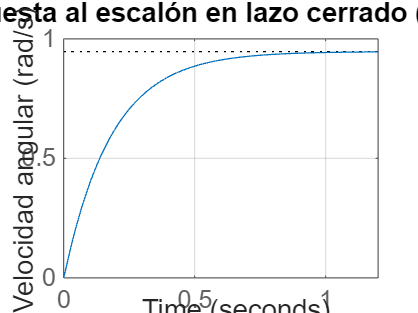


% --- Gráficas del sistema continuo ---
figure;
step(G1); % Se grafica comúnmente la respuesta en lazo cerrado
grid on;
title("Respuesta al escalón en lazo cerrado (Continuo)");
ylabel('Velocidad angular (rad/s)');



% =========================================================================
%                         ANÁLISIS DISCRETO
% =========================================================================

% Discretización de la planta
Ts = 0.01; % Tiempo de muestreo (ajustar si es necesario)
disp('Función de transferencia de velocidad en lazo abierto (Discreta):')

Función de transferencia de velocidad en lazo abierto (Discreta):


G_z = c2d(G, Ts, 'tustin'); % 'tustin' es un método común de discretización

% Función de transferencia discreta en lazo cerrado
disp('Función de transferencia de velocidad en lazo cerrado (Discreta):')

Función de transferencia de velocidad en lazo cerrado (Discreta):


G1_z = feedback(G_z, 1)

G1_z =
 
  0.02124 z^2 + 0.04247 z + 0.02124
  ---------------------------------
     1.021 z^2 - 0.31 z - 0.6215
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


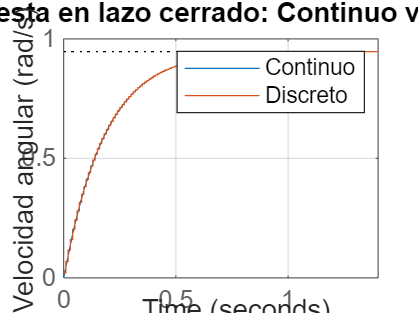


% --- Gráficas de comparación Continuo vs. Discreto ---
figure;
step(G1);
hold on;
step(G1_z);
hold off;
grid on;
title('Respuesta en lazo cerrado: Continuo vs. Discreto');
ylabel('Velocidad angular (rad/s)');
legend('Continuo', 'Discreto');


% Extracción de datos de la función de transferencia discreta
disp('Parámetros del sistema discreto en lazo abierto:');

Parámetros del sistema discreto en lazo abierto:


NumZ = G_z.Numerator{1}   % Coeficientes del numerador discreto

NumZ =     0.0212    0.0425    0.0212


DenZ = G_z.Denominator{1}   % Coeficientes del denominador discreto

DenZ =     1.0000   -0.3524   -0.6428


[z, p, k] = zpkdata(G_z, 'v') % Ceros, polos y ganancia discretos

z =     -1
    -1


p =     0.9971
   -0.6447


k = 0.0212



% =========================================================================
%                  CONFIGURACIÓN DEL CONTROLADOR PID
% =========================================================================
% Este bloque define un controlador PID discreto y analiza el
% comportamiento del sistema en lazo cerrado con dicho controlador.
% =========================================================================

% Coeficientes del controlador PID
P = 0.96133;
I = 1.3635;
D = -0.0016302;
N = 589.7114; % Coeficiente del filtro derivativo

% Término Proporcional
C_p = tf(P, 1, Ts);

% Término Integral: I*Ts / (z - 1)
C_i = tf(I * Ts, [1 -1], Ts);

% Término Derivativo con filtro: (D*N)*(z - 1) / (z - 1 + N*Ts)
num_d = D * N * [1 -1];       % Numerador: D*N*(z - 1)
den_d = [1, (N * Ts - 1)];    % Denominador: (z - 1 + N*Ts)
C_d = tf(num_d, den_d, Ts);

% Controlador PID completo (suma de los términos)
disp('Función de transferencia PID discreta:')

Función de transferencia PID discreta:


C_pid = C_p + C_i + C_d

C_pid =
 
  -1.752e-05 z^2 + 5.683 z - 5.602
  --------------------------------
       z^2 + 3.897 z - 4.897
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties




% Sistema en lazo cerrado con el controlador PID
disp('Función de transferencia del sistema controlado:')

Función de transferencia del sistema controlado:


T = feedback(C_pid * G_z, 1)

T =
 
  -3.722e-07 z^4 + 0.1207 z^3 + 0.1224 z^2 - 0.1173 z - 0.119
  -----------------------------------------------------------
        z^4 + 3.665 z^3 - 6.791 z^2 - 0.8964 z + 3.029
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


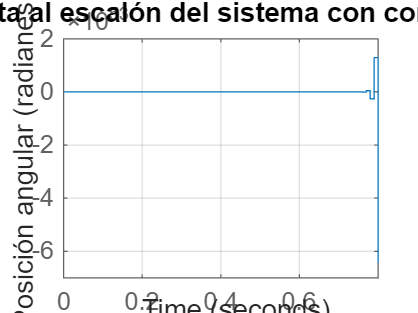


% --- Gráfica del sistema controlado ---
figure;
step(T);
grid on;
title('Respuesta al escalón del sistema con controlador PID');
ylabel('Posición angular (radianes)');